# Figure S7E

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'A037_data.mat'],'S','settings','allIF');


conditions = settings.conditions

conditions = 8×6 cell array
    {'NR86 DMSO'    }    {[1 2 3 4]}    {[2 3]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'NR86 DMSO TAK'}    {[1 2 3 4]}    {[4 5]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'NR86 DOX DMSO'}    {[1 2 3 4]}    {[6 7]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'NR86 DOX TAK' }    {[1 2 3 4]}    {[8 9]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'NR87 DMSO'    }    {[5 6 7 8]}    {[2 3]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'NR87 DMSO TAK'}    {[5 6 7 8]}    {[4 5]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'NR87 DOX DMSO'}    {[5 6 7 8]}    {[6 7]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'NR87 DOX TAK' }    {[5 6 7 8]}    {[8 9]}    {[1]}    {[0 0 0]}    {[0 10]}

framesPerHr = 60/12;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = (frameDrugAdded - S(i).POI)/framesPerHr;
end

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
  

    for n = 1:length(dat.POI(:,1))
       if dat.POI(n,1) + round(.5*framesPerHr) <= numFrames & dat.POI(n,1) > 1 * framesPerHr
            apcExpressGate(n) = dat.apcNormM(n,dat.POI(n,1) + round(.5*framesPerHr)) < .2 & ...
               dat.apcNormM(n,dat.POI(n,1) - 1 * framesPerHr) > .5 ;
       end
      

    end
    S(i).apcExpressGate = apcExpressGate;

end

S7E left

conds=[5 7];
timeGate = [0 5];
S_ind = 3;
cols =  [.5 .5 .5; 0 .1 .9];
linetype = {'-','-','-','--'};
% CRL activation post mitosis
figure('unit','inches','position',[0 0 4 6]), hold on
POI_align = 3;
POI_cal = 6;
data_out = [];
frames_out = [];
for i=1:length(conds)
    data = S(conds(i));
    % inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
    %     S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
    %     S(conds(i)).apcExpressGate & (S(conds(i)).POI_realtime(:,S_ind) > drug_time | isnan(S(conds(i)).POI(:,S_ind)) );

 inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) & S(conds(i)).apcExpressGate & S(conds(i)).goodCdk;% &...
   
sum(inds)
    event = data.POI(:,POI_cal);
    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

    
     y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of POI_cal relative to POI_align
    lost = lost/framesPerHr; % lost = last frame relative to POI_align
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);
    y_filt = y(inds);
    censor_filt = censor(inds);
    [f,x] = ecdf(y_filt,'Censoring',censor_filt);
    if isempty(f)
        f = 0;
        x = 0;
    end
    y_max = max(y_filt(censor_filt));
    if x(end) < y_max
        x(end+1) = y_max;
        f(end + 1) = f(end);
    end
    if f(end) == 1
        x(end+1) = 1000;
        f(end + 1) = f(end);
    end
     if x(1) ~= 0
        x0 = 0;
        f0 = 0;
        f = cat(1,f0,f);
        x = cat(1,x0,x);
     end 

    plot(x,f,'Color',cols(i,:),'LineStyle',linetype(i),'linewidth',2);
    % plot(x,f); 

%     sum(inds)
end

ans = 915

ans = 1499

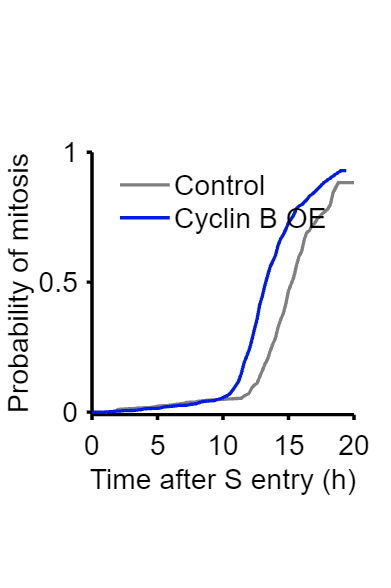

% legend(conditions(conds,1));
axis square
set(gca,'linewidth',2,'FontSize',17)
legend('Control','Cyclin B OE','Box','off','Location','north','FontSize',17);
xlim([0 20]); 
xticks(0:5:20)
ylim([-.01 1]);
xlabel('Time after S entry (h)')
ylabel('Probability of mitosis')
hold on

 % print_pdf(['fig_S7E_left.pdf'])

S7E middle

conds=[5 7];
clear cols
colors =  [.5 .5 .5; 0 .1 .9];
POI_align = 3;
ally = [];
groups = [];
timeGate = [0 5];

for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = ~isnan(data.POI(:,POI_align)) &  ...
         data.POI_realtime(:,1) <= timeGate(2) & data.POI_realtime(:,1) >= timeGate(1) & data.apcExpressGate & data.goodCdk;
sum(inds)
    yvals = (data.POI_realtime(inds,3) - data.POI_realtime(inds,1));
    yvals = yvals(yvals < 200000 & yvals >= -200000);
    ally = [ally; yvals];
    groups = [groups; repmat(i,size(yvals))];
    meang1(i) = mean(yvals);
    length(yvals);
    cols(i,1) = ({colors(i,:)}');
    groupcol = repmat([colors([1:i],:)],1,1);
 

end

ans = 915

ans = 1499

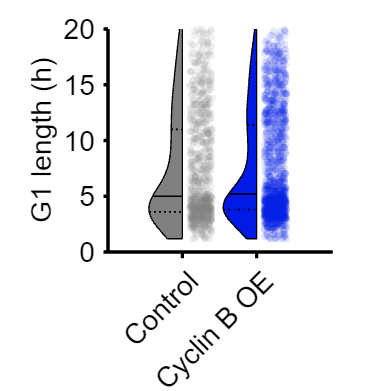


figure('Units', 'Inches', 'Position', [0, 0, 4 4])
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',.5,'histOri','left','widthDiv',[2 1],'color','black');

set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.1);
ylabel([ 'G1 length (h)'])


xticklabels({'Control','Cyclin B OE'})
ylim([0 20])
yticks(-10:5:20)
 xtickangle(45)
 hline(0,'--k')
axis square
set(gca,'fontsize',17,'linewidth',2)

 p=mediantest(ally(groups==1),ally(groups==2))

p = 0.3875


% print_pdf(['fig_S7E_middle.pdf'])

S7E right

conds=[5 7];


colors = [.5 .5 .5; 0 .1 .9];
linetype = {'-','-','-','--'};
timeGate = [0 5];

figure('unit','inches','position',[0 0 4 4])
hold on
axis square;
POI_align = 3;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
          inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) & S(conds(i)).apcExpressGate & S(conds(i)).goodCdk;% &...
 sum(inds)


    ydata = data.cdk(inds,:);

    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',2,'linestyle',linetype(i)});
end

ans = 915

ans = 1499

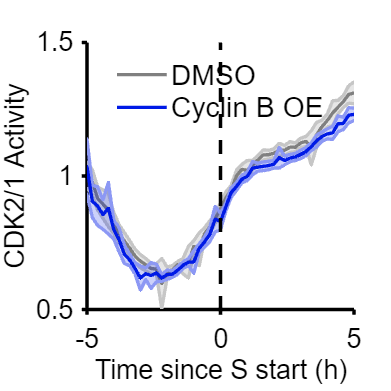


ylabel({'CDK2/1 Activity'});xlabel('Time since S start (h)');
legend('DMSO','Cyclin B OE','box','off','Location','north','fontsize',17);

xlim([-5 5]); 
ylim([.5 1.5]);
vline([0],'k--')

% print_pdf(['fig_S7E_right.pdf'])